## NETFLIX Userbase Dataset

NetflixUserbase = readtable("NetflixUserbase.csv")

NetflixUserbase = 2500×10 table
    UserID    SubscriptionType    MonthlyRevenue     JoinDate     LastPaymentDate         Country          Age      Gender          Device        PlanDuration
    ______    ________________    ______________    __________    _______________    __________________    ___    __________    ______________    ____________

       1        {'Basic'   }            10          0015-01-22      0010-06-23       {'United States' }    28     {'Male'  }    {'Smartphone'}    {'1 Month'} 
       2        {'Premium' }            15          0005-09-21      0022-06-23       {'Canada'        }    35     {'Female'}    {'Tablet'    }    {'1 

## Data Distribution

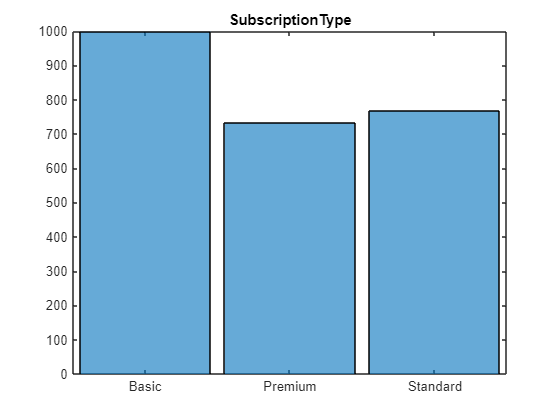

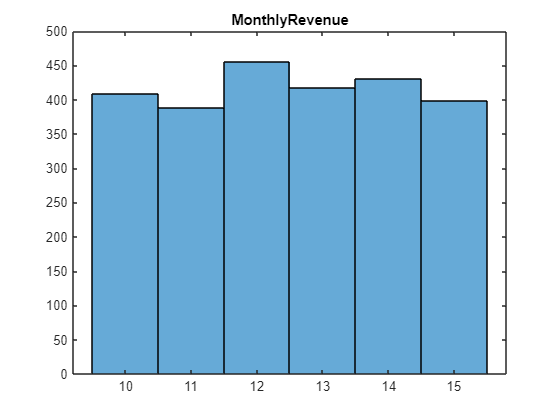

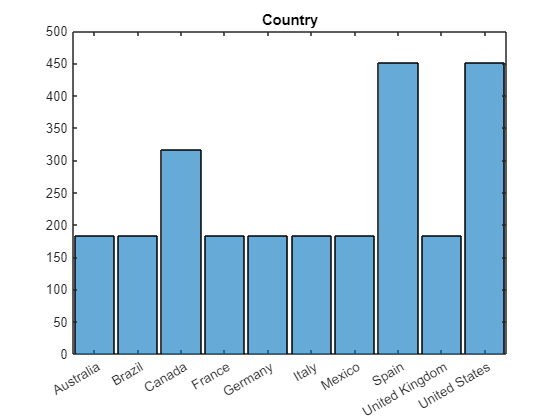

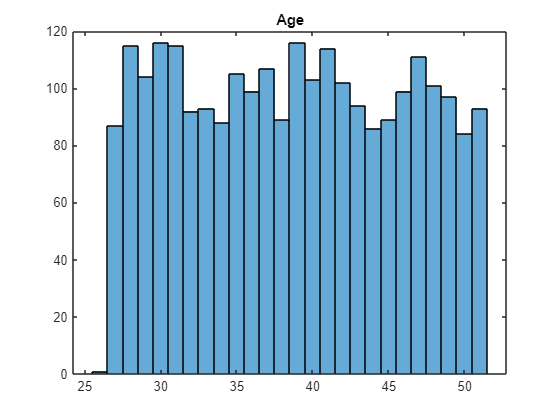

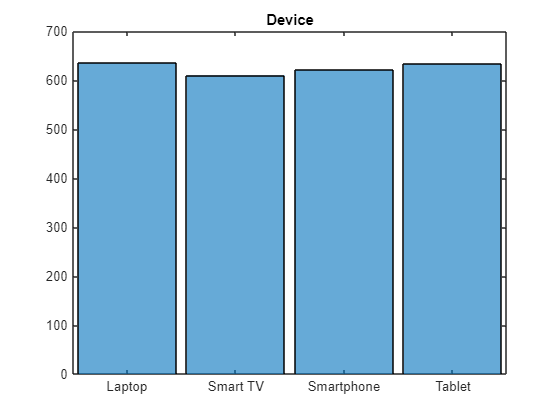

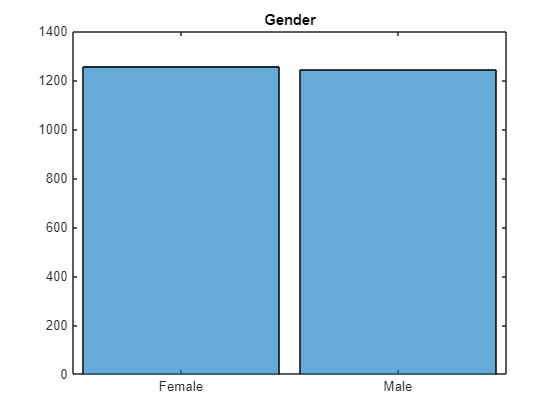

% Define variables to analyze
NumericVars = ["SubscriptionType", "MonthlyRevenue", "Country", "Age", "Device", "Gender"];

% Loop through the variables
for v = 1:numel(NumericVars)
    figure;
    varData = NetflixUserbase{:, NumericVars(v)};
    
    % Check if the data is numeric
    if isnumeric(varData)
        histogram(varData);
    elseif iscategorical(varData) || isstring(varData) || iscellstr(varData)
        % Convert to categorical if not already
        categoricalData = categorical(varData);
        histogram(categoricalData);
    else
        % Skip unsupported types with a warning
        warning('Skipping variable %s as it is neither numeric nor categorical.', NumericVars(v));
        continue;
    end
    
    % Set the title of the histogram
    title(replace(NumericVars(v), "_", " "));
end

## Data Cleaning

Handling Duplicate Value

NoDuplicates = unique(NetflixUserbase, 'rows');
disp('Dataset after removing duplicates:');

Dataset after removing duplicates:


disp(NoDuplicates);

    UserID    SubscriptionType    MonthlyRevenue     JoinDate     LastPaymentDate         Country          Age      Gender          Device        PlanDuration
    ______    ________________    ______________    __________    _______________    __________________    ___    __________    ______________    ____________

        1       {'Basic'   }            10          0015-01-22      0010-06-23       {'United States' }    28     {'Male'  }    {'Smartphone'}    {'1 Month'} 
        2       {'Premium' }            15          0005-09-21      0022-06-23       {'Canada'        }    35     {'Female'}    {'Tablet'    }    {'1 Month'} 
        3       {'Stand

% Check for duplicates
numDuplicates = height(NetflixUserbase) - height(unique(NetflixUserbase, 'rows'));

if numDuplicates > 0
    disp(['Duplicates found: ', num2str(numDuplicates), ' duplicate rows.']);
else
    disp('No duplicates found.');
end

No duplicates found.


Handling Missing Values

missingSummary = sum(ismissing(NoDuplicates));
disp('Summary of missing values in each column:');

Summary of missing values in each column:


disp(missingSummary);

     0     0     0     0     0     0     0     0     0     0



Detecting Outliers

% Define numeric columns (assuming the dataset contains numeric columns)
numericData = NetflixUserbase(:, varfun(@isnumeric, NetflixUserbase, 'OutputFormat', 'uniform'));

% Initialize logical array to mark outliers
outliers = false(size(numericData));

% Detect outliers using Z-score method
for i = 1:width(numericData)
    columnData = numericData{:, i};
    zScores = (columnData - mean(columnData, 'omitnan')) / std(columnData, 'omitnan');
    outliers(:, i) = abs(zScores) > 3; % Mark values with Z-score > 3 as outliers
end

% Display outlier counts for each column
disp('Outlier counts for each numeric column:');

Outlier counts for each numeric column:


disp(sum(outliers));

     0     0     0



% Remove rows with any outliers
rowsWithOutliers = any(outliers, 2); % Rows with at least one outlier
dataCleaned = NetflixUserbase(~rowsWithOutliers, :); % Retain rows without outliers

% Display cleaned dataset
disp('Dataset after removing outliers:');

Dataset after removing outliers:


disp(dataCleaned);

    UserID    SubscriptionType    MonthlyRevenue     JoinDate     LastPaymentDate         Country          Age      Gender          Device        PlanDuration
    ______    ________________    ______________    __________    _______________    __________________    ___    __________    ______________    ____________

        1       {'Basic'   }            10          0015-01-22      0010-06-23       {'United States' }    28     {'Male'  }    {'Smartphone'}    {'1 Month'} 
        2       {'Premium' }            15          0005-09-21      0022-06-23       {'Canada'        }    35     {'Female'}    {'Tablet'    }    {'1 Month'} 
        3       {'Stand

## GEOGRAPHICAL ANALYSIS

Let's plot using geoplot to see the actual choropleth maps representation which countries are colored based on their revenue.

countryRevenue = varfun(@sum, NetflixUserbase, 'InputVariables', 'MonthlyRevenue', ...
                        'GroupingVariables', 'Country');
countryRevenue = sortrows(countryRevenue, 'sum_MonthlyRevenue', 'descend');
disp(countryRevenue)

         Country          GroupCount    sum_MonthlyRevenue
    __________________    __________    __________________

    {'United States' }       451               5664       
    {'Spain'         }       451               5662       
    {'Canada'        }       317               3950       
    {'United Kingdom'}       183               2318       
    {'Italy'         }       183               2317       
    {'France'        }       183               2307       
    {'Brazil'        }       183               2285       
    {'Australia'     }       183               2271       
    {'Germany'       }       183               2260       
    {'Mexico'        }       183               2237       



subTypeDist = groupsummary(NetflixUserbase, {'Country', 'SubscriptionType'}, 'sum', 'MonthlyRevenue');
disp(subTypeDist);

         Country          SubscriptionType    GroupCount    sum_MonthlyRevenue
    __________________    ________________    __________    __________________

    {'Australia'     }      {'Basic'   }          31                378       
    {'Australia'     }      {'Premium' }         101               1254       
    {'Australia'     }      {'Standard'}          51                639       
    {'Brazil'        }      {'Basic'   }         146               1824       
    {'Brazil'        }      {'Premium' }          33                410       
    {'Brazil'        }      {'Standard'}           4                 51       
    {'Canada'        }      {'Basic'   }         145               1816       
    {'Canada'        }      {'Premium' }          88               1086       
    {'Canada'        }      {'Standard'}          84               1048  

.zip files is downloaded from Natural Earth > Cultural Vector 1.110m > Admin 0 – Countries. Make sure the folder is unzip and the folder is open when running the code.

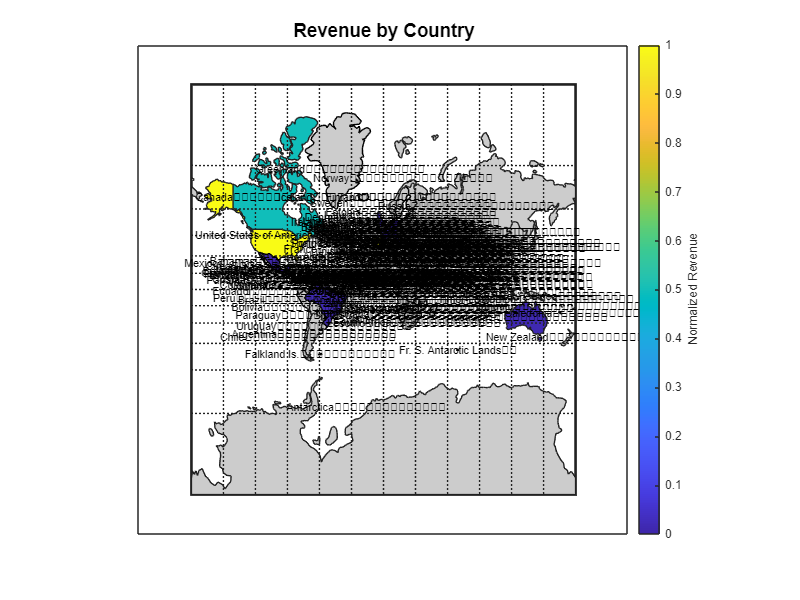

% Load country shapefile data
worldData = shaperead('ne_110m_admin_0_countries.shp', 'UseGeoCoords', true);

% Create a world map
figure('Position', [100, 100, 800, 600]); % Adjust the size as needed
axesm('mercator', 'MapLatLimit', [-90 90], 'MapLonLimit', [-180 180]);
setm(gca, 'Frame', 'on', 'Grid', 'on');
geoshow(worldData, 'FaceColor', [0.8 0.8 0.8]); % Plot countries

% Loop through each country to add labels
for k = 1:length(worldData)
    % Get the centroid of each country for label placement
    lat = mean(worldData(k).Lat(~isnan(worldData(k).Lat)));
    lon = mean(worldData(k).Lon(~isnan(worldData(k).Lon)));
    
    % Add country name as a label
    if ~isempty(worldData(k).NAME)
        textm(lat, lon, worldData(k).NAME, 'FontSize', 8, 'HorizontalAlignment', 'center');
    end
end

% Add title
title('Country Names on World Map', 'FontSize', 14);

world = readgeotable('ne_110m_admin_0_countries.shp');
world.NAME = strrep(world.NAME, "United States of America", "United States");


% Extract top 10 revenue countries
[~, topIndices] = maxk(countryRevenue.sum_MonthlyRevenue, 10); % Indices of top 10 revenue values
topRevenueCountries = countryRevenue.Country(topIndices); % Names of countries in the top 10
topRevenueValues = countryRevenue.sum_MonthlyRevenue(topIndices); % Revenue values for top 10 countries

% Match top revenue countries with the shapefile data
[isMatch, idx] = ismember(world.NAME, topRevenueCountries);

% Add revenue data to the shapefile table (only for matched countries)
world.Revenue = NaN(height(world), 1); % Initialize revenue column
world.Revenue(isMatch) = topRevenueValues(idx(isMatch));

% Normalize revenue for coloring
validRevenueValues = world.Revenue(isMatch); % Only valid top 10 revenue values
minRevenue = min(validRevenueValues);
maxRevenue = max(validRevenueValues);
normalizedRevenue = (validRevenueValues - minRevenue) / (maxRevenue - minRevenue);

% Apply colormap
colormap(parula);
faceColors = parula(256); % Define a 256-color colormap
colorIdx = round(normalizedRevenue * 255) + 1;

% Plot only countries in the top 10 revenue list
hold on;
for k = 1:height(world)
    if ~isnan(world.Revenue(k)) % Only plot countries with top 10 revenue
        % Get the country shape
        countryShape = worldData(k);

        % Determine color based on revenue
        revenueColor = faceColors(colorIdx(k == find(isMatch)), :);

        % Plot the country with its corresponding color
        geoshow(countryShape, 'FaceColor', revenueColor);
    end
end
hold off;

% Add a colorbar
c = colorbar;
c.Label.String = 'Normalized Revenue (Top 10 Countries)';
title('Top 10 Revenue by Country', 'FontSize', 14);
hold off;

% Add a colorbar
c = colorbar;
c.Label.String = 'Normalized Revenue';
title('Revenue by Country', 'FontSize', 14);

## REVENUE CONTRIBUTION BY COUNTRY

From Total Revenue, how many percentage each of the country contributed. This can helps Netflix to focus more on promoting and improving customer experience in the country that contribute the highest to its company. 

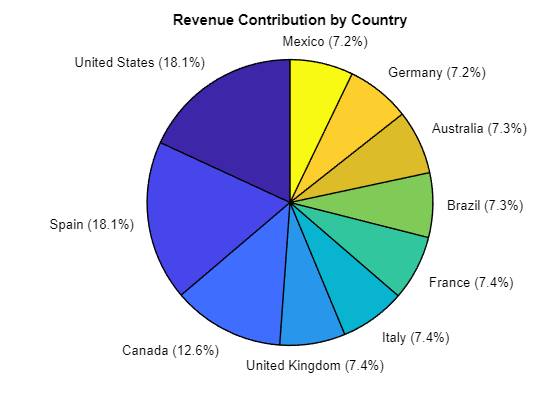

countryRevenue.Properties.VariableNames{'sum_MonthlyRevenue'} = 'TotalRevenue' ;
countryRevenue.Properties.VariableNames{'GroupCount'} = 'TotalUsers';

% Extract data for pie chart
countries = countryRevenue.Country; % Country names
revenue = countryRevenue.TotalRevenue; % Total revenue for each country

% Calculate percentages for the labels
percentages = revenue / sum(revenue) * 100;
labels = strcat(countries, ' (', string(round(percentages, 1)), '%)');

% Plot the pie chart
figure;
pie(revenue, labels);
title('Revenue Contribution by Country');

## MARKET PENETRATION ANALYSIS

From World Bank Group, the Most Recent Value (Thousands) of people Population is used to calculate the percentage of a country’s population that uses Netflix

countries = {'United States', 'Spain', 'Canada', 'United Kingdom', 'Italy', ...
             'France', 'Brazil', 'Australia', 'Germany', 'Mexico'}';

populations = [334.9, 48.3, 39.0, 68.4, 59.0, 68.3, 220.1, 26.4, 83.3, 129.7]';
populationTable = table(countries, populations, 'VariableNames', {'Country', 'Population (Thousands)'});
disp(populationTable);

         Country          Population (Thousands)
    __________________    ______________________

    {'United States' }            334.9         
    {'Spain'         }             48.3         
    {'Canada'        }               39         
    {'United Kingdom'}             68.4         
    {'Italy'         }               59         
    {'France'        }             68.3         
    {'Brazil'        }            220.1         
    {'Australia'     }             26.4         
    {'Germany'       }             83.3         
    {'Mexico'        }            129.7         



% table countryRevenue is combined with populationTable
marketPenetration = join(countryRevenue, populationTable, 'Keys', 'Country');
marketPenetration.Penetration = (marketPenetration.TotalUsers ./ marketPenetration.("Population (Thousands)")) * 100; % in percentage
disp(marketPenetration);

         Country          TotalUsers    TotalRevenue    Population (Thousands)    Penetration
    __________________    __________    ____________    ______________________    ___________

    {'United States' }       451            5664                334.9               134.67   
    {'Spain'         }       451            5662                 48.3               933.75   
    {'Canada'        }       317            3950                   39               812.82   
    {'United Kingdom'}       183            2318                 68.4               267.54   
    {'Italy'         }       183            2317                   59               310.17   
    {'France'        }       183            2307                 68.3               267.94   
    {'Brazil'        }       183            2285                220.1        

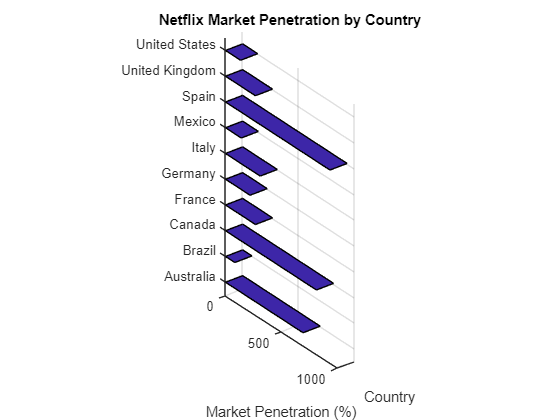


figure;
bar3h(categorical(marketPenetration.Country), marketPenetration.Penetration);
xlabel('Country');
ylabel('Market Penetration (%)');
title('Netflix Market Penetration by Country');

## **Subscription Type Analysis**

Data Cleaning

% Group data by SubscriptionType and Device to count occurrences
deviceUsageTable = groupcounts(NetflixUserbase, {'SubscriptionType', 'Device'})

deviceUsageTable = 12×4 table
    SubscriptionType        Device        GroupCount    Percent
    ________________    ______________    __________    _______

      {'Basic'   }      {'Laptop'    }       259         10.36 
      {'Basic'   }      {'Smart TV'  }       238          9.52 
      {'Basic'   }      {'Smartphone'}       251         10.04 
      {'Basic'   }      {'Tablet'    }       251         10.04 
      {'Premium' }      {'Laptop'    }       192          7.68 
      {'Premium' }      {'Smart TV'  }       188          7.52 
      {'Premium' }      {'Smartphone'}       171          6.84 
      {'Premium' }      {'Tablet'    }       182          7.28 
      {'Standard'}      {'Laptop'    }       185           7.4 
      {'Standard'}      {'Smart TV'  }       184          7.36 
      {'Standard'}      {'Smartphone'}       199          7.96 
 


% Rename the columns for better readability
deviceUsageTable.Properties.VariableNames = {'SubscriptionType', 'Device', 'UserCount', 'Percent'}

deviceUsageTable = 12×4 table
    SubscriptionType        Device        UserCount    Percent
    ________________    ______________    _________    _______

      {'Basic'   }      {'Laptop'    }       259        10.36 
      {'Basic'   }      {'Smart TV'  }       238         9.52 
      {'Basic'   }      {'Smartphone'}       251        10.04 
      {'Basic'   }      {'Tablet'    }       251        10.04 
      {'Premium' }      {'Laptop'    }       192         7.68 
      {'Premium' }      {'Smart TV'  }       188         7.52 
      {'Premium' }      {'Smartphone'}       171         6.84 
      {'Premium' }      {'Tablet'    }       182         7.28 
      {'Standard'}      {'Laptop'    }       185          7.4 
      {'Standard'}      {'Smart TV'  }       184         7.36 
      {'Standard'}      {'Smartphone'}       199         7.96 
      {'Standa


% Define the desired order for SubscriptionType
categories = {'Basic', 'Standard', 'Premium'}

categories = 1×3 cell array
    {'Basic'}    {'Standard'}    {'Premium'}



% Extract unique devices
devices = unique(deviceUsageTable.Device)

devices = 4×1 cell array
    {'Laptop'    }
    {'Smart TV'  }
    {'Smartphone'}
    {'Tablet'    }



% Prepare data for grouped bar chart
dataMatrix = zeros(numel(categories), numel(devices)); % Preallocate a matrix to store user counts
for i = 1:height(deviceUsageTable)
    rowIdx = find(strcmp(categories, deviceUsageTable.SubscriptionType(i))); % Match subscription type to its ordered index
    colIdx = find(strcmp(devices, deviceUsageTable.Device(i))); % Match device to its index
    dataMatrix(rowIdx, colIdx) = deviceUsageTable.UserCount(i) % Populate the data matrix
end

dataMatrix =    259     0     0     0
     0     0     0     0
     0     0     0     0


dataMatrix =    259   238     0     0
     0     0     0     0
     0     0     0     0


dataMatrix =    259   238   251     0
     0     0     0     0
     0     0     0     0


dataMatrix =    259   238   251   251
     0     0     0     0
     0     0     0     0


dataMatrix =    259   238   251   251
     0     0     0     0
   192     0     0     0


dataMatrix =    259   238   251   251
     0     0     0     0
   192   188     0     0


dataMatrix =    259   238   251   251
     0     0     0     0
   192   188   171     0


dataMatrix =    259   238   251   251
     0     0     0     0
   192   188   171   182


dataMatrix =    259   238   251   251
   185     0     0     0
   192   188   171   182


dataMatrix =    259   238   251   251
   185   184     0     0
   192   188   171   182


dataMatrix =    259   238   251   251
   185   184   199     0
   192   188   171   182


dataMatrix =    259   238   251   251
   185   184   199   200
   192   188   171   182



% Plot the grouped bar chart
figure; % Opens a new figure window
bar(dataMatrix, 'grouped');
set(gca, 'XTickLabel', categories); % Set x-axis labels to the desired order
title('Device Usage by Subscription Type');
xlabel('Subscription Type');
ylabel('Number of Users');
legend(devices, 'Location', 'Best');

## **Time Series Analysis**

Data Cleaning

% Convert the datetime array to a character array
incorrectJoinDate = string(NetflixUserbase.JoinDate);
incorrectLastPaymentDate = string(NetflixUserbase.LastPaymentDate);

% Define a function to adjust the date format
function fixedDate = adjustDateFormat(dateStr)
    % Extract day, month, and year from the incorrect format
    day = extractBetween(dateStr, 3, 4);   % Extract day (characters 3-4)
    month = extractBetween(dateStr, 6, 7); % Extract month (characters 6-7)
    year = extractBetween(dateStr, 9, 10); % Extract last two digits of the year
    
    % Correct the year to be in the 2000 century
    year = strcat('20', year);
    
    % Combine into the correct format 'DD-MM-20YY'
    fixedDate = strcat(day, '-', month, '-', year);
end

% Apply the function to adjust all dates in the 'JoinDate' column
fixedJoinDate = arrayfun(@adjustDateFormat, incorrectJoinDate, 'UniformOutput', true); % output as a string array
fixedLastPaymentDate = arrayfun(@adjustDateFormat, incorrectLastPaymentDate, 'UniformOutput', true);

% Convert the fixed dates to MATLAB datetime format
NetflixUserbase.JoinDate = datetime(fixedJoinDate, 'InputFormat', 'dd-MM-yyyy');
NetflixUserbase.LastPaymentDate = datetime(fixedLastPaymentDate, 'InputFormat', 'dd-MM-yyyy');

% Display the updated table
disp(NetflixUserbase);

    UserID    SubscriptionType    MonthlyRevenue     JoinDate      LastPaymentDate         Country          Age      Gender          Device        PlanDuration
    ______    ________________    ______________    ___________    _______________    __________________    ___    __________    ______________    ____________

        1       {'Basic'   }            10          15-Jan-2022      10-Jun-2023      {'United States' }    28     {'Male'  }    {'Smartphone'}    {'1 Month'} 
        2       {'Premium' }            15          05-Sep-2021      22-Jun-2023      {'Canada'        }    35     {'Female'}    {'Tablet'    }    {'1 Month'} 
        3       {'S

The first plot helps identify whether the retention period is increasing, decreasing, or stable over time

% Calculate the duration (in days) between JoinDate and LastPaymentDate
NetflixUserbase.ActivityDuration = days(NetflixUserbase.LastPaymentDate - NetflixUserbase.JoinDate)

NetflixUserbase = 2500×11 table
    UserID    SubscriptionType    MonthlyRevenue     JoinDate      LastPaymentDate         Country          Age      Gender          Device        PlanDuration    ActivityDuration
    ______    ________________    ______________    ___________    _______________    __________________    ___    __________    ______________    ____________    ________________

       1        {'Basic'   }            10          15-Jan-2022      10-Jun-2023      {'United States' }    28     {'Male'  }    {'Smartphone'}    {'1 Month'}           511       
       2        {'Premium' }            15          0

% Group data by JoinDate to analyze trends over time
[uniqueJoinDates, ~, groupIdx] = unique(NetflixUserbase.JoinDate);
averageDurations = accumarray(groupIdx, NetflixUserbase.ActivityDuration, [], @mean)

averageDurations =    655
   647
   635
   624
   614
   601
   596
   592
   577
   574


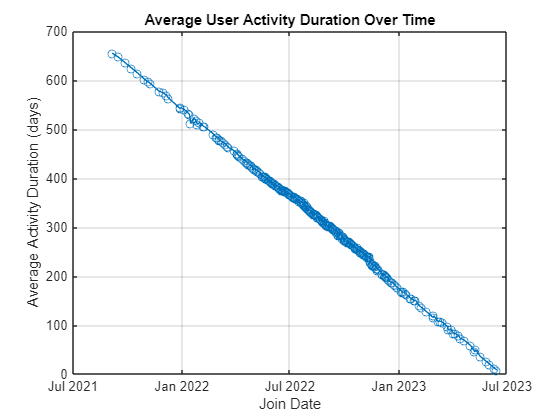


% Plot the average activity duration over JoinDate
figure;
plot(uniqueJoinDates, averageDurations, '-o');
xlabel('Join Date');
ylabel('Average Activity Duration (days)');
title('Average User Activity Duration Over Time');
grid on;

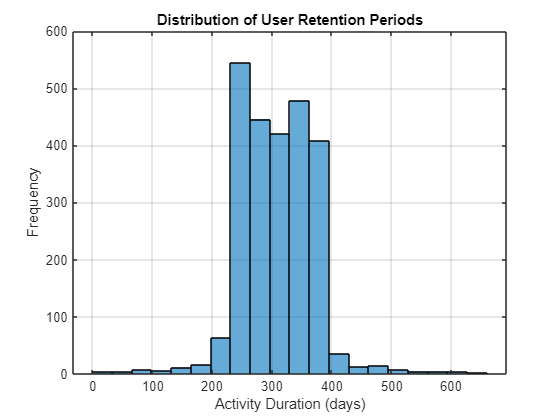

%The histogram reveals how retention is distributed among users (e.g., short-term vs. long-term users)
% Optional: Histogram of user retention periods
figure;
histogram(NetflixUserbase.ActivityDuration, 20); % 20 bins for visualization
xlabel('Activity Duration (days)');
ylabel('Frequency');
title('Distribution of User Retention Periods');
grid on;

## **Churn rate & prediction**

To find the rate of the short-term churn rate & long-term churn rate.

To predict the churn users based on the want to identify it as long-term churn or short-term churn

% Define churn label (active for less than 8 months)
churn_threshold1 = 243;

% calculate churn rate
churned_users1 = NetflixUserbase.ActivityDuration < churn_threshold1;
churn_rate1 = mean(churned_users1);

% Display the churn rate
fprintf('Churn Rate: %.2f%%\n', churn_rate1 * 100);

Churn Rate: 8.72%


%Define churn label
churn_threshold2 = 400; %(active for more than 400days)

%calculate churn rate
churned_users2 = NetflixUserbase.ActivityDuration > churn_threshold2;
churn_rate2 = mean(churned_users2);
fprintf('Long-Term Churn Rate: %.2f%%\n', churn_rate2* 100);

Long-Term Churn Rate: 3.00%


%total churn rate for whole dataset
churn_rate3 = churn_rate1 + churn_rate2

churn_rate3 = 0.1172


% Display the churn rate
fprintf('Churn Rate: %.2f%%\n', churn_rate3 * 100);

Churn Rate: 11.72%


% Display updated table with DaysActive and churn information
NetflixUserbase.Churn = churned_users1; % Add churn column to table
disp(NetflixUserbase);

    UserID    SubscriptionType    MonthlyRevenue     JoinDate      LastPaymentDate         Country          Age      Gender          Device        PlanDuration    ActivityDuration    Churn
    ______    ________________    ______________    ___________    _______________    __________________    ___    __________    ______________    ____________    ________________    _____

        1       {'Basic'   }            10          15-Jan-2022      10-Jun-2023      {'United States' }    28     {'Male'  }    {'Smartphone'}    {'1 Month'}           511           false
        2       {'Premiu

% Drop unnecessary columns (e.g., UserID, JoinDate, LastPaymentDate)
NetflixUserbase.UserID = [];
NetflixUserbase.JoinDate = [];
NetflixUserbase.LastPaymentDate = [];
NetflixUserbase.PlanDuration = [];

% Step 3: Prepare data for machine learning
% Convert categorical features to numeric
% Convert MonthlyRevenue and other relevant variables to categorical
NetflixUserbase.MonthlyRevenue = categorical(NetflixUserbase.MonthlyRevenue);
NetflixUserbase.SubscriptionType = categorical(NetflixUserbase.SubscriptionType);
NetflixUserbase.Country = categorical(NetflixUserbase.Country);
NetflixUserbase.Gender = categorical(NetflixUserbase.Gender);
NetflixUserbase.Device = categorical(NetflixUserbase.Device)

NetflixUserbase = 2500×8 table
    SubscriptionType    MonthlyRevenue       Country        Age    Gender      Device      ActivityDuration    Churn
    ________________    ______________    ______________    ___    ______    __________    ________________    _____

        Basic                 10          United States     28     Male      Smartphone          511           false
        Premium               15          Canada            35     Female    Tablet              655           false
        Standard              12          United Kingdom    42     Male      Smart TV            119           true 
        Standard              12          Australia         51     Female    Laptop              351           

% Define predictors and response
predictors = NetflixUserbase(:, {'MonthlyRevenue', 'SubscriptionType', 'ActivityDuration', 'Age'})  % Features for prediction

predictors = 2500×4 table
    MonthlyRevenue    SubscriptionType    ActivityDuration    Age
    ______________    ________________    ________________    ___

          10              Basic                 511           28 
          15              Premium               655           35 
          12              Standard              119           42 
          12              Standard              351           51 
          10              Basic                  58           33 
          15              Premium               466           29 
          12              Standard              563           46 
          10              Basic                  83           39 
          12              Standard              246           37 
          15              Premium               166           44 
          10              Basic              

response = NetflixUserbase.Churn  % output

response = 2500×1 logical array
   0
   0
   1
   0
   1
   0
   0
   1
   0
   1


% Set the seed for reproducibility
rng(42); % Ensure reproducibility

% Train-test split (80% train, 20% test)
cv = cvpartition(size(NetflixUserbase, 1), 'HoldOut', 0.3);  % 20% for testing
trainData = NetflixUserbase(training(cv), :)

trainData = 1750×8 table
    SubscriptionType    MonthlyRevenue       Country        Age    Gender      Device      ActivityDuration    Churn
    ________________    ______________    ______________    ___    ______    __________    ________________    _____

        Standard              12          United Kingdom    42     Male      Smart TV            119           true 
        Standard              12          Australia         51     Female    Laptop              351           false
        Basic                 10          Germany           33     Male      Smartphone           58           true 
        Basic                 10          Mexico            39     Female    Laptop               83           true 


testData = NetflixUserbase(test(cv), :)

testData = 750×8 table
    SubscriptionType    MonthlyRevenue       Country        Age    Gender      Device      ActivityDuration    Churn
    ________________    ______________    ______________    ___    ______    __________    ________________    _____

        Basic                 10          United States     28     Male      Smartphone          511           false
        Premium               15          Canada            35     Female    Tablet              655           false
        Premium               15          France            29     Female    Smart TV            466           false
        Standard              12          Brazil            46     Male      Tablet              563           false
  

% Extract predictor values and response for training and testing
X_train = trainData(:, {'MonthlyRevenue', 'SubscriptionType', 'ActivityDuration', 'Age'}); 
y_train = trainData.Churn;

X_test = testData(:, {'MonthlyRevenue', 'SubscriptionType', 'ActivityDuration', 'Age'}); 
y_test = testData.Churn;

% Identify numerical columns
numericalcols = {'Age', 'ActivityDuration'};

% Normalize numerical features in the training set
[X_train_num_norm, mu, sigma] = normalize(table2array(X_train(:, numericalcols)));

% Apply the same normalization to the testing set
X_test_num_norm = (table2array(X_test(:, numericalcols)) - mu) ./ sigma;

% Combine normalized numerical features with categorical features
X_train_combined = [array2table(X_train_num_norm, 'VariableNames', numericalcols), ...
                    X_train(:, {'SubscriptionType', 'MonthlyRevenue'})]

X_train_combined = 1750×4 table
      Age       ActivityDuration    SubscriptionType    MonthlyRevenue
    ________    ________________    ________________    ______________

     0.43498         -3.0007            Standard              12      
      1.6833         0.69927            Standard              12      
    -0.81336         -3.9735            Basic                 10      
    0.018864         -3.5748            Basic                 10      
    -0.25854        -0.97528            Standard              12      
     0.71239         -2.2511            Premium               15      
     -1.0908          1.5126            Basic                 10      
     0.85109         -3.3515            Premium               15      
     -1.6456         0.34842            Basic                 10      
    -0.39725          2.2143            Premium   


X_test_combined = [array2table(X_test_num_norm, 'VariableNames', numericalcols), ...
                   X_test(:, {'SubscriptionType', 'MonthlyRevenue'})]

X_test_combined = 750×4 table
      Age       ActivityDuration    SubscriptionType    MonthlyRevenue
    ________    ________________    ________________    ______________

     -1.5069           3.251            Basic                 10      
    -0.53595          5.5475            Premium               15      
     -1.3682          2.5333            Premium               15      
     0.98979          4.0803            Standard              12      
      1.2672          4.2557            Standard              12      
    -0.11984         -4.1011            Standard              12      
     -1.2295          3.3467            Basic                 10      
      1.4059           4.176            Standard              12      
     -1.0908          2.2622            Standard              12      
     0.15757          -3.208            Basic       

% Train a random forest classifier
randomForestModel = fitcensemble(X_train_combined, y_train, ...
'Method', 'Bag', 'NumLearningCycles', 100);

% Display model details
disp(randomForestModel);

  ClassificationBaggedEnsemble
           PredictorNames: {'Age'  'ActivityDuration'  'SubscriptionType'  'MonthlyRevenue'}
             ResponseName: 'Y'
    CategoricalPredictors: [3 4]
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 1750
               NumTrained: 100
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
                FResample: 1
                  Replace: 1
         UseObsForLearner: [1750×100 logical]


  Properties, Methods



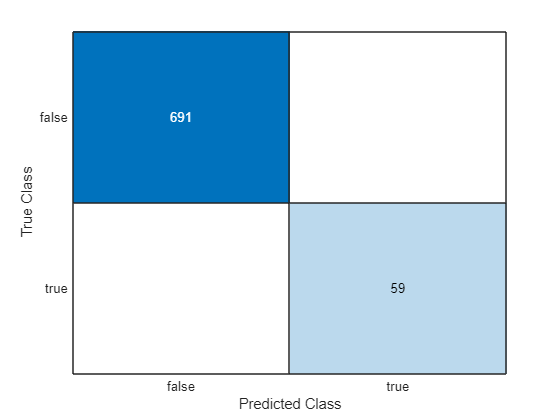

% Predict on the test set
y_pred = predict(randomForestModel, X_test_combined);

% Plot the confusion matrix
confusionchart(y_test, y_pred);


% Calculate evaluation metrics
accuracy = sum(y_pred == y_test) / numel(y_test);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 100.00%


% Compute precision, recall, and F1-score
confusion = confusionmat(y_test, y_pred);
precision = confusion(2,2) / sum(confusion(:,2));
recall = confusion(2,2) / sum(confusion(2,:));
f1_score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);

Precision: 1.00


fprintf('Recall: %.2f\n', recall);

Recall: 1.00


fprintf('F1-Score: %.2f\n', f1_score);

F1-Score: 1.00


% Save the trained model for future use
save('trainedModel.mat', 'randomForestModel');
%load('trainedModel.mat');